
%#ok<*CLALL>

clear all;clc 

% Sim settings. 
maxSpeed = 1E-1; 
timeStep = 4; 

% Initial states. 
x_c_0 = [-1; -1]; 
x_e_0 = [1; 0; 0; maxSpeed]; 

% Evader position estimation. 
x_e = x_e_0(1:2)+timeStep*x_e_0(3:4); 

% Position constraints. 
areaBnds = [-1; 1; -1; 1]*50; 

% Position constraint test. 
% areaBnds(2) = -0.8; 

% TPBVP test time span input. 
tspan = 0 : 1E-1 : timeStep; 

% Initial guess. 
guess = [x_e; 0; 0]; 
solGuess = bvpinit(tspan, guess); 
options = bvpset("Stats", "on"); 
sol = bvp4c( ...
    @(t, y) eqns(t, y, maxSpeed, areaBnds), ...
    @(y_a, y_b) boundaryConditions(y_a, y_b, x_c_0, x_e), ...
    solGuess, options); 

The solution was obtained on a mesh of 41 points.
The maximum residual is  4.855e-15. 
There were 668 calls to the ODE function. 
There were 26 calls to the BC function. 


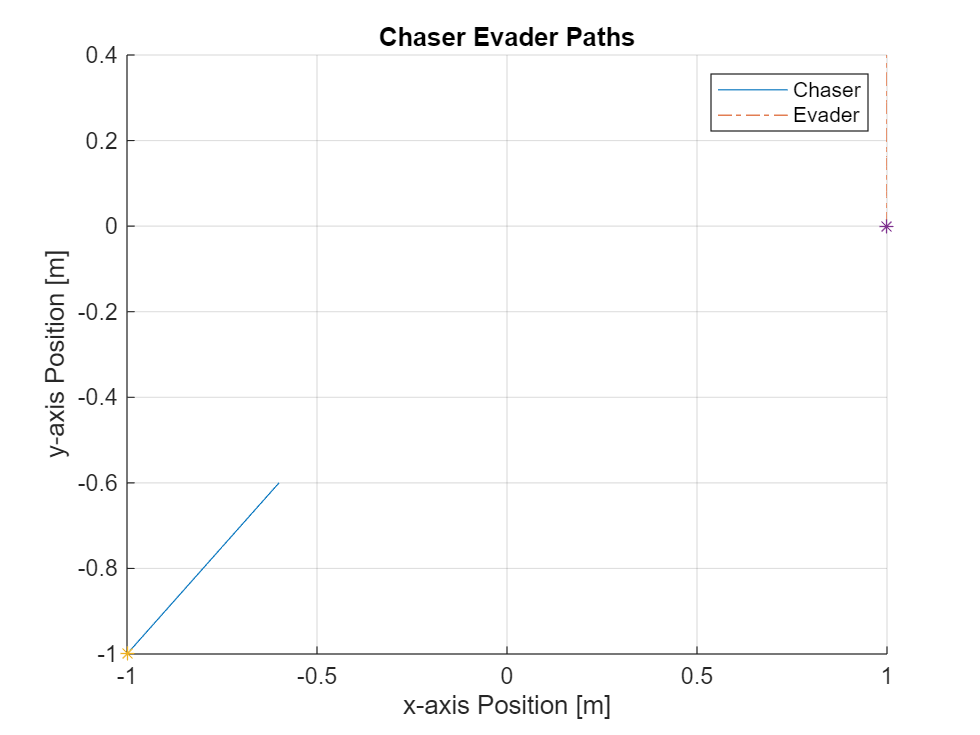

% solGuess = bvpinit(tspan, sol.y(:, end)); 
% sol = bvp4c( ...
%     @(t, y) eqns(t, y, maxSpeed, areaBnds), ...
%     @(y_a, y_b) boundaryConditions(y_a, y_b, x_c_0, x_e), ...
%     solGuess, options); 
tspan = sol.x; 
y = sol.y; 
chaserPath = y(1:2, :); 
evaderPath = x_e_0(1:2)+tspan.*x_e_0(3:4); 

clf; 
hold on; 
grid on; 
plot(chaserPath(1, :), chaserPath(2, :)); 
plot(evaderPath(1, :), evaderPath(2, :), "-."); 
plot(chaserPath(1, 1), chaserPath(2, 1), "*"); 
plot(evaderPath(1, 1), evaderPath(2, 1), "*"); 
title("Chaser Evader Paths"); 
xlabel("x-axis Position [m]"); 
ylabel("y-axis Position [m]"); 
legend("Chaser", "Evader"); 
% axis([-2 1 -1 1.6]); 
hold off;  

% Compare packaged function. 
chaserTPBVP(x_c_0, x_e_0, maxSpeed, areaBnds, timeStep)

ans =    -0.6000
   -0.6000



% Differential equations. 
function dydt = eqns(~, y, maxSpeed, areaBnds)
    % Equivalence threshold. 
    eps = 1E-3; 

    % Optimal Control. 
    u = (abs(y(3:4))>eps) .* -sign(y(3:4))*maxSpeed; 
    
    % Position and velocity constraints. 
    if y(1) < areaBnds(1)
        u(1) = maxSpeed; 
    elseif areaBnds(2) < y(1)
        u(1) = -maxSpeed; 
    end
    if y(2) < areaBnds(3)
        u(2) = maxSpeed; 
    elseif areaBnds(4) < y(2)
        u(2) = -maxSpeed; 
    end

    A = [zeros(2)]; 
    B = [eye(2)]; 

    dydt = [ ...
        A*y(1:2)+B*u; ...
        zeros(2, 1)]; 
end

% Boundary conditions. 
function retval = boundaryConditions(y_a, y_b, x_c_0, x_e)
    retval = [ ...
        y_a(1:2)-x_c_0; ...
        y_b(3:4)-(y_b(1:2)-x_e)]; 
end